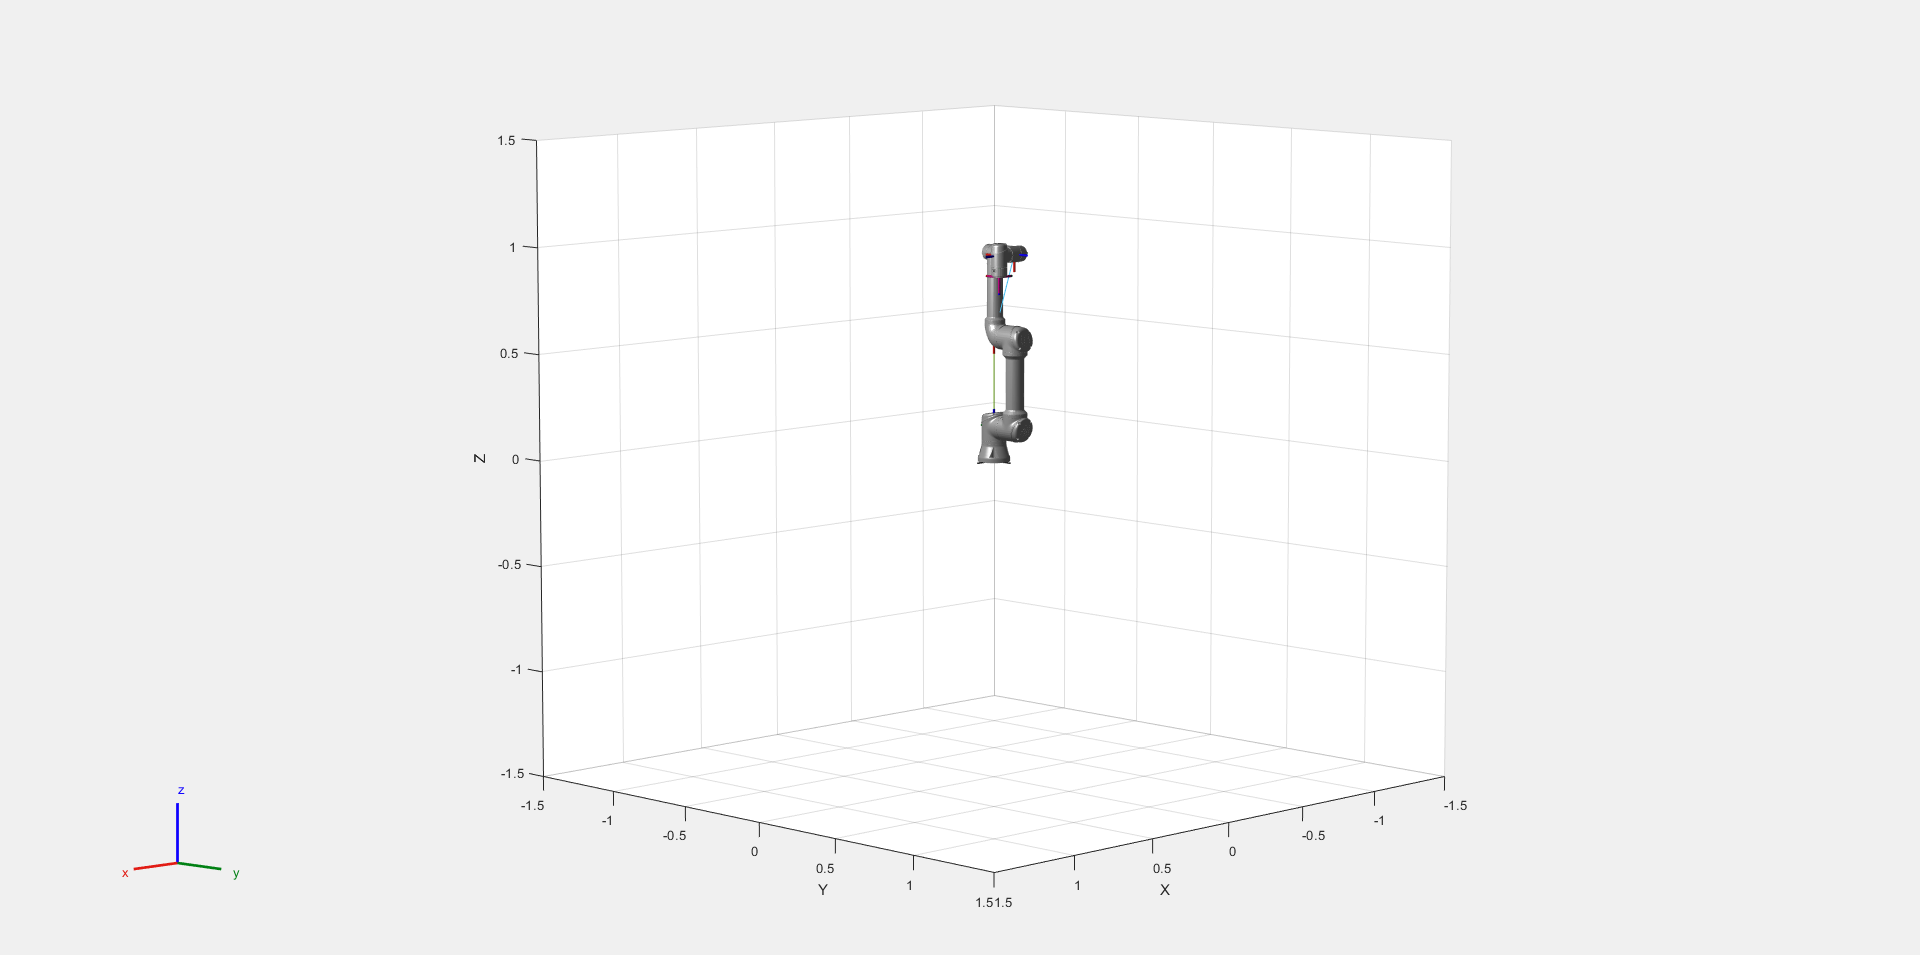

% Carrega o modelo
UR5e = loadrobot('universalUR5e');

% Define a pose desejada
config = homeConfiguration(UR5e);
config(1).JointPosition = 0;         % shoulder_pan_joint
config(2).JointPosition = -pi/2;     % shoulder_lift_joint
config(3).JointPosition = 0;         % elbow_joint
config(4).JointPosition = 0;         % wrist_1_joint
config(5).JointPosition = -pi/2;     % wrist_2_joint
config(6).JointPosition = 0;         % wrist_3_joint

% % Armazena as transformações desejadas antes de fixar as juntas
% T2 = getTransform(UR5e, config, 'wrist_2_link', 'wrist_1_link');
% T3 = getTransform(UR5e, config, 'wrist_3_link', 'wrist_2_link');
% 
% % Cria juntas fixas com as transformações obtidas
% J2 = rigidBodyJoint('fixed_wrist_2','fixed');
% setFixedTransform(J2, T2);
% 
% J3 = rigidBodyJoint('fixed_wrist_3','fixed');
% setFixedTransform(J3, T3);
% 
% % Substitui as juntas revolutas pelas fixas
% replaceJoint(UR5e, 'wrist_2_link', J2);
% replaceJoint(UR5e, 'wrist_3_link', J3);
% 
% config = homeConfiguration(UR5e);
% config(1).JointPosition = 0;        % shoulder_pan_joint
% config(2).JointPosition = -pi/2;    % shoulder_lift_joint
% config(3).JointPosition = 0;        % elbow_joint
% 
% shoulder_pan_joint.PositionLimits = [-pi/2 pi/2];  
% shoulder_lift_joint.PositionLimits = [-pi/2 pi/2]; 
% elbow_joint.PositionLimits = [0 pi];

%Visualiza o novo modelo
show(UR5e, config);

showdetails(UR5e);

--------------------
Robot: (10 bodies)

 Idx                Body Name                         Joint Name                         Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                         ----------                         ----------                ----------------   ----------------
   1                     base         base_link-base_fixed_joint                              fixed                    base_link(0)   
   2        base_link_inertia        base_link-base_link_inertia                              fixed                    base_link(0)   shoulder_link(3)  
   3            shoulder_link                 shoulder_pan_joint                           revolute            base_link_inertia(2)   upper_arm_link(4)  
   4           upper_arm_link                shoulder_lift_joint                           revolute                shoulder_link(3)   forearm_link(5)  
   5             forearm_link                        elbow_join